# SectionD: Clustering & Classification 

## Q1:

### a: Apply your choice of a clustering algorithm (that we covered in class) to the PVT data

K-means

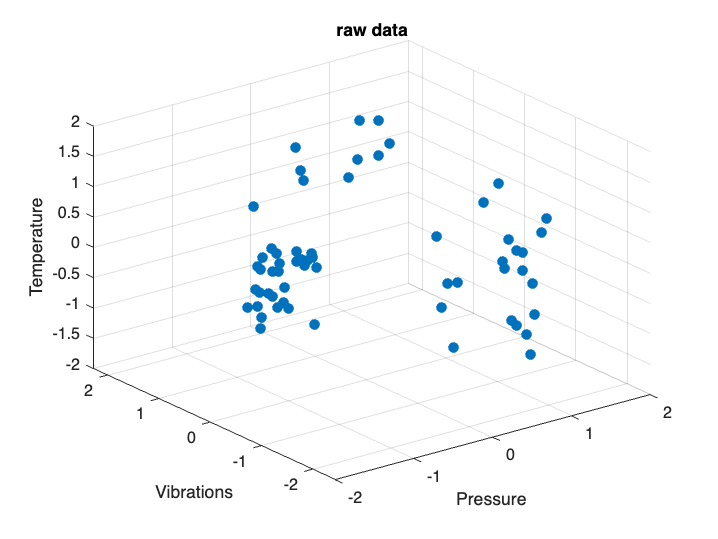

clear;clc;
load('F1_PVT.mat');

% reshape data from tensor (10x3x6) to matrix (60x3)
shape = size(F1_PVT);
data = [];
for i = 1: shape(3)
    data = [data;F1_PVT(:,:,i)];
end

% normalize the data
data = normalize(data,'zscore');

% visulize the original data
figure(1);
clf('reset');
plot3(data(:,1),data(:,2),data(:,3),'.','MarkerSize',20);
grid on;
title("raw data")
xlabel('Pressure');
ylabel('Vibrations');
zlabel("Temperature");

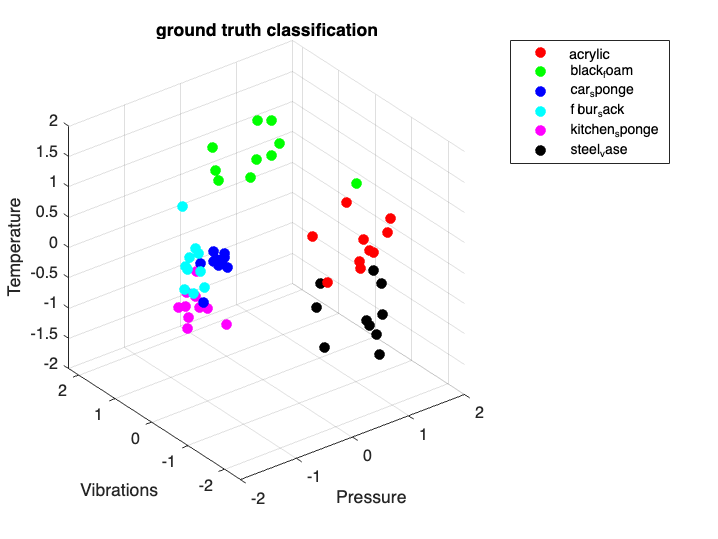


% visulize the original data with color
figure(2);
str = ["acrylic","black_foam","car_sponge","flour_sack","kitchen_sponge","steel_vase"];
clf('reset');
colors = ["r", "g", "b", "c", "m", "k"];
for i = 1:size(data,1)/10
    x = data(10*(i-1)+1:10*i,1);
    y = data(10*(i-1)+1:10*i,2);
    z = data(10*(i-1)+1:10*i,3);
    plot3(x,y,z,'.','color',colors(i),'MarkerSize',20);
    hold on;
end
grid on;
title("ground truth classification")
legend(str);
xlabel('Pressure');
ylabel('Vibrations');
zlabel("Temperature");
hold off;

matrice = "euclidean"

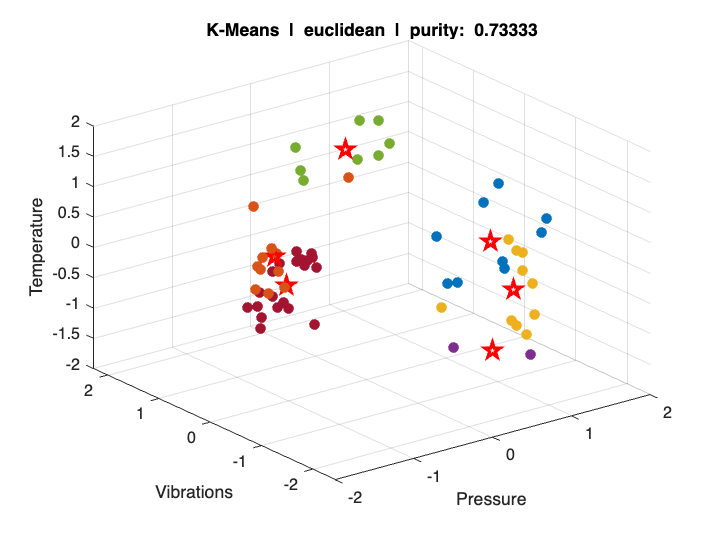

matrice = "cosine"

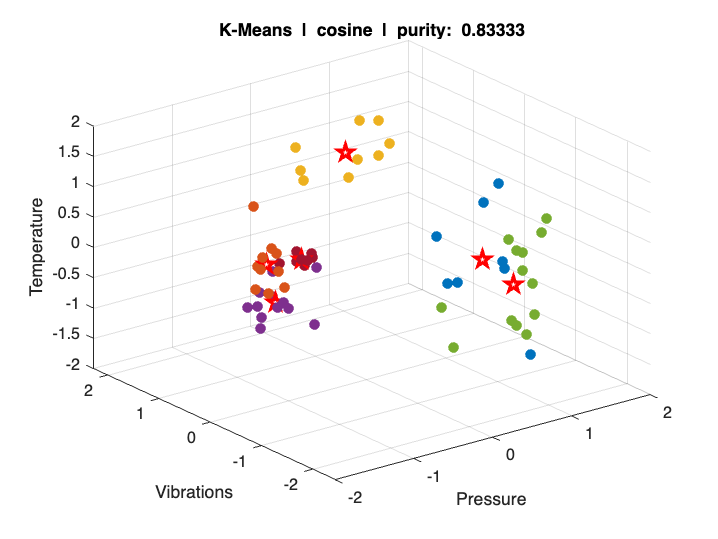

matrice = "cityblock"

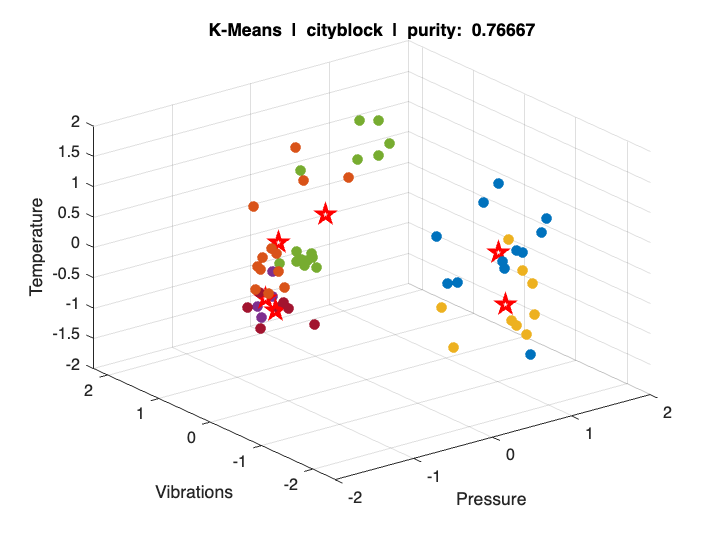

matrice = "minkowski"

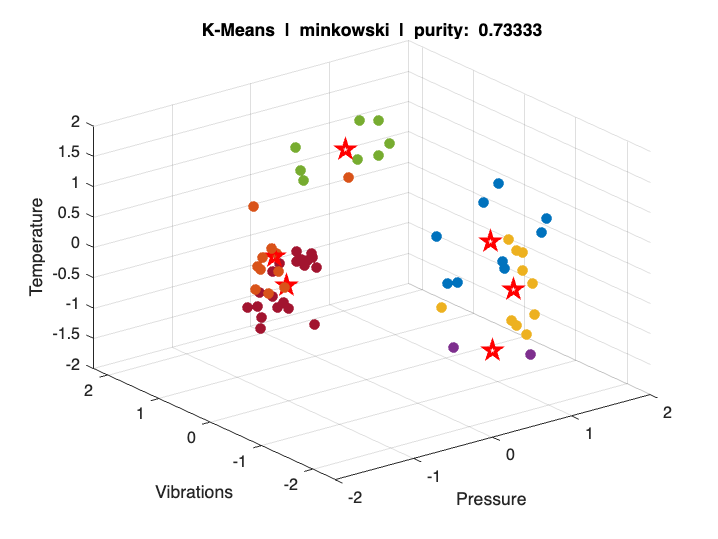

matrice = "chebychev"


% avaliable distance matrix:
% matrices = ["euclidean","cosine",'hamming','cityblock','minkowski','chebychev','jaccard','spearman'];
matrices = ["euclidean","cosine","cityblock","minkowski","chebychev"];
for matrice = matrices
    matrice
    [clusters, centroids] = KMeans(data,6,matrice,2023);
    % ---visualize kmeans results ---
    figure();
    clf('reset');
    shape = size(clusters);
    for i = 1:shape(2)
        group_data = cell2mat(clusters(i));
        plot3(group_data(:,1),group_data(:,2),group_data(:,3),'.','MarkerSize',20);
        hold on;
        plot3(centroids(i,1),centroids(i,2),centroids(i,3),'pentagram','MarkerSize',10,'color','r','LineWidth',2)
        hold on;
    end
    grid on; 
    hold off;
    purity_score = purity(clusters,data);
    title("K-Means  |  "+matrice+"  |  purity:  "+purity_score);
    xlabel('Pressure');
    ylabel('Vibrations');
    zlabel("Temperature");

end

### Bagging

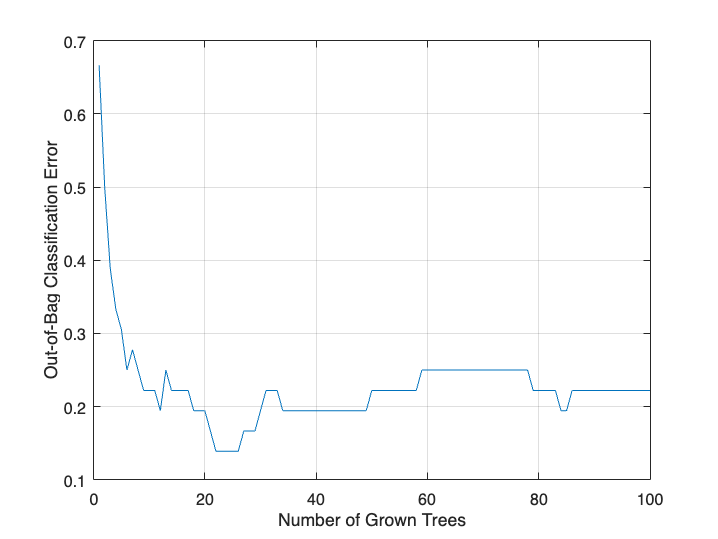

clc;clear;
load("F1_E_3D.mat");
rng(2023);
X = reduced_data;

% --- Set the training / testing sets ratio ---
train_set_ratio = 0.6;
% ---------------------------------------------

label = ["steel","kitchen","flour","car","black","acrylic"];
% splitting the data set
X_train = [];
X_test = [];
for i = 1:length(label)
    data = X(10*(i-1)+1:10*i,:);
    X_train = [X_train;data(1:10*train_set_ratio,:)];
    X_test = [X_test;data(10*train_set_ratio+1:10,:)];
end

% creating the labels 
Y_train = [];
Y_test = [];
for i = 1:length(X_train)
    Y_train = [Y_train;label(ceil(i/(10*train_set_ratio)))];
end
for i = 1:length(X_test)
    Y_test = [Y_test;label(ceil(i/(10-10*train_set_ratio)))];
end

% Bagging algorithm 
Mdl = TreeBagger(100,X_train,Y_train,...
      Method="classification",...
      OOBPrediction="on");
% --- visualize the results ---
plot(oobError(Mdl));
xlabel("Number of Grown Trees");
ylabel("Out-of-Bag Classification Error");
grid on;


"23 number of bags is optima"

ans = "23 number of bags is optima"

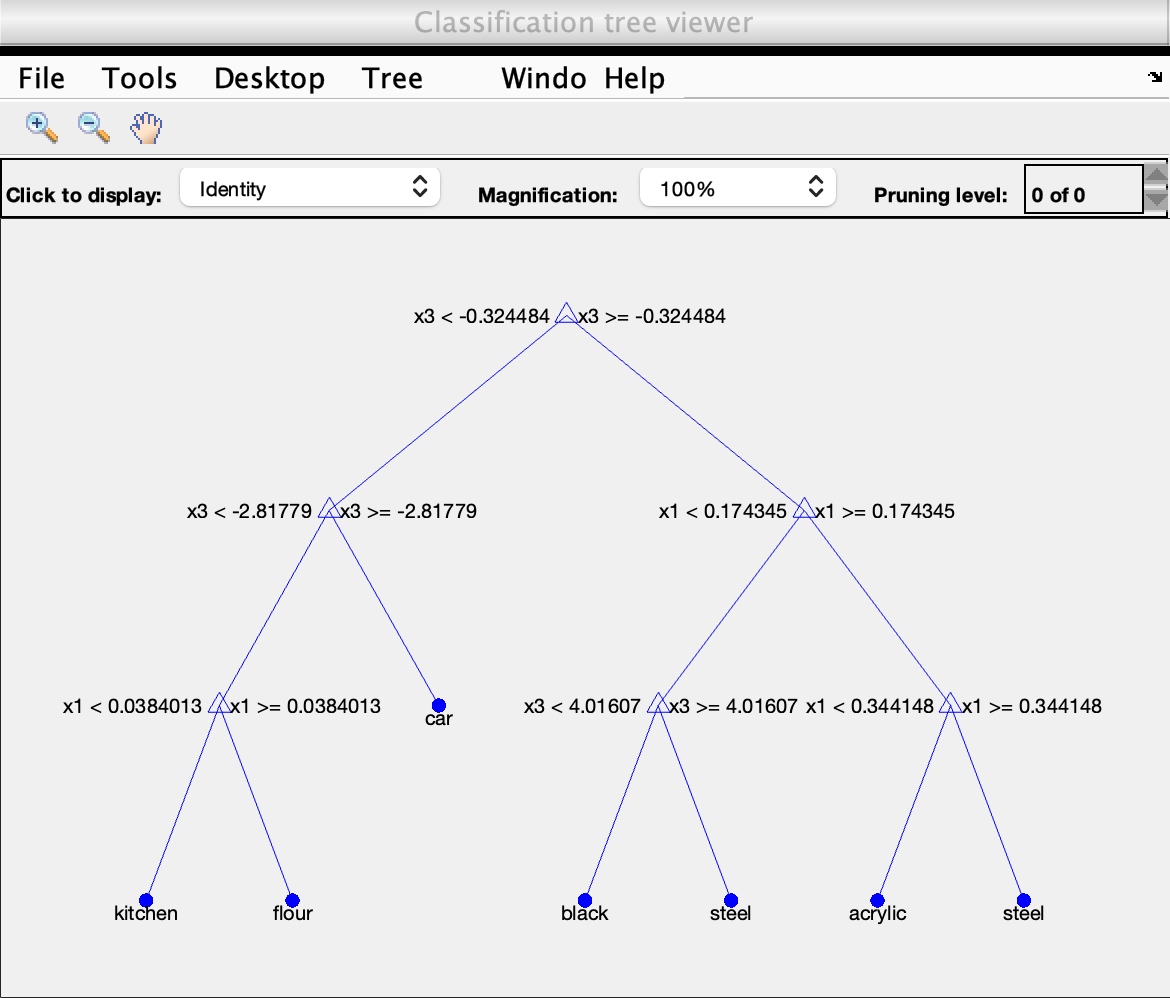

Mdl = TreeBagger(23,X_train,Y_train,...
      Method="classification");

view(Mdl.Trees{1},Mode="graph");

"Graph view of decision tree 1"

ans = "Graph view of decision tree 1"

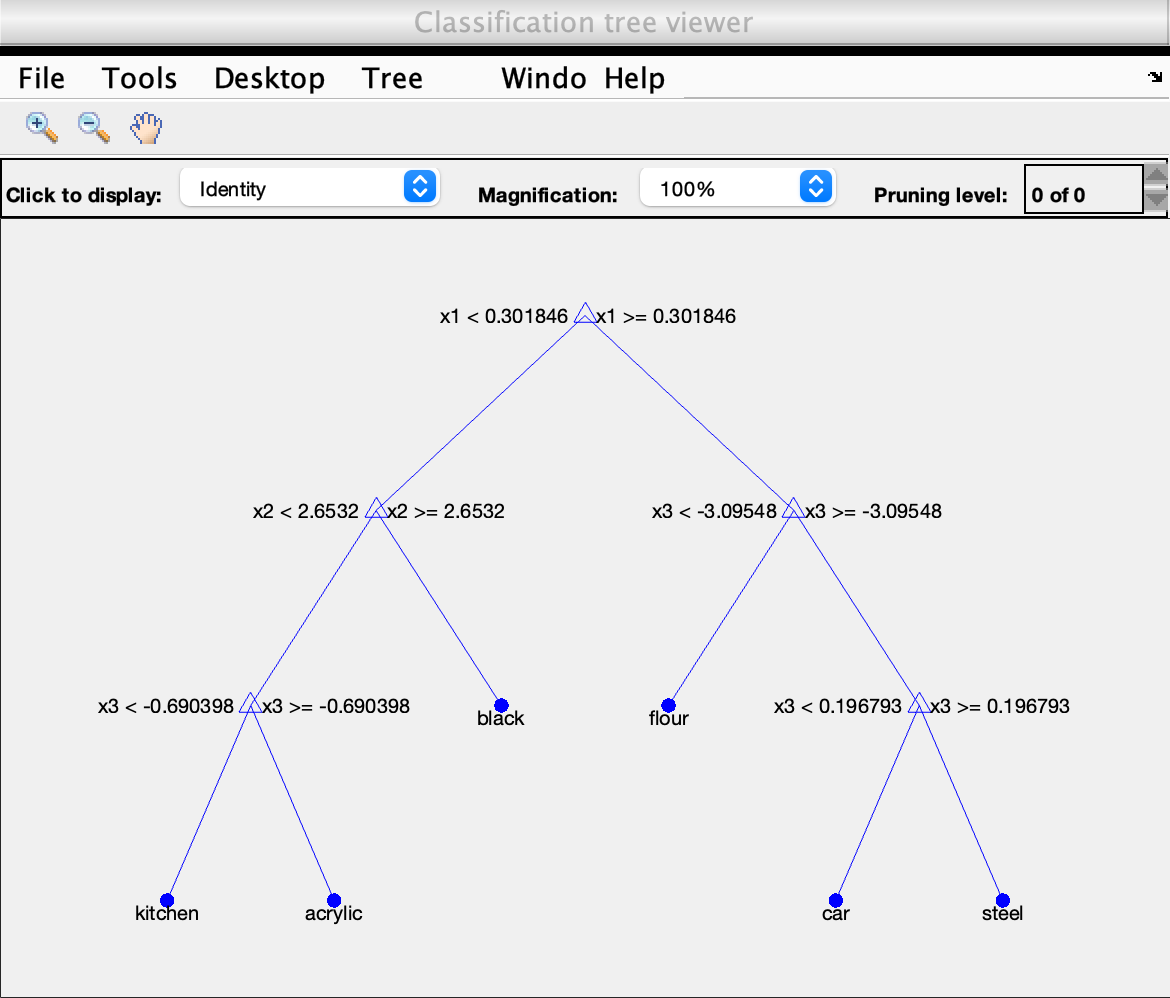

view(Mdl.Trees{15},Mode="graph");

"Graph view of decision tree 15"

ans = "Graph view of decision tree 15"

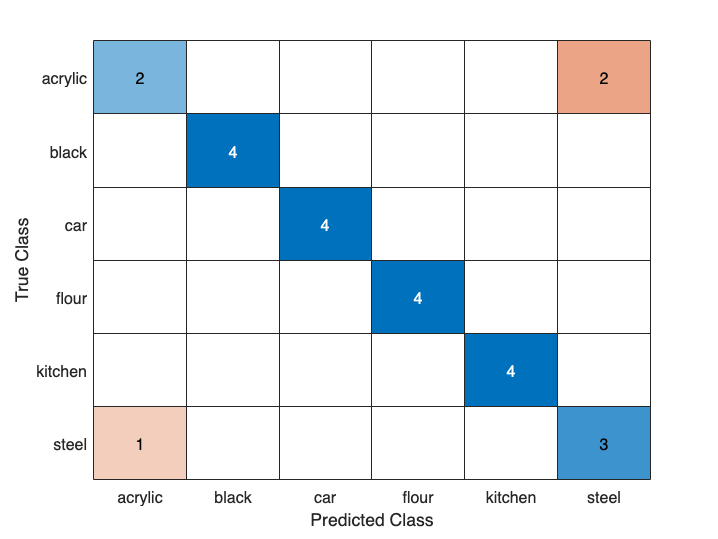


% Prediction on test set
Y_test_hat = predict(Mdl,X_test);
confus_mat = confusionmat(Y_test, Y_test_hat);
confusionchart(confus_mat,label);

function score = purity(clusters,data)
%% Evaluate the clustering results:
    correct_count = zeros(1,6);
    shape = size(clusters);
    for i = 1:shape(2)
        cluster_count = zeros(1,shape(2));
        cluster_result = cell2mat(clusters(i));
        num = size(cluster_result);
        for j = 1:num
            obj = cluster_result(j,:);
            class = find(ismember(data,obj,'row'));
            class = ceil(class/10);
            cluster_count(class) = cluster_count(class)+1;
        end
        correct_count(i) = max(cluster_count);
    end
    score = sum(correct_count) / 60;
end


function [clusters, centroids] = KMeans(data,K,dis_metrice,seed)
    rng(seed);
    last_custers = cell(1,K);
    centroids = 2*rand(K,3)-1;
    shape = size(data);
    converge = false;
    while ~converge
        clusters = cell(1,K);
        for i = 1:shape(1)
            % for each datapoint
            dist = [];
            n_points = size(centroids);
            % compute the distance between the point and the centroid
            for j = 1:n_points(1)
                dist = [dist,pdist([data(i,:);centroids(j,:)],dis_metrice)];
            end
            % find the centroid with the smallest distance
            [~,min_I] = min(dist);
            % Assign each datapoint to the nearest centroid
            clusters(min_I) = {[cell2mat(clusters(min_I));data(i,:)]};
        end

        % calculate the mean of each cluster, update centroids
        centroids = [];
        for i = 1:n_points(1)
            cluster = cell2mat(clusters(i));
            ave = [mean(cluster(:,1)),mean(cluster(:,2)),mean(cluster(:,3))];
            centroids = [centroids; ave];
        end

        % check convergence:
        for i = 1:K
            converge = all(size(cell2mat(last_custers(i)))==size(cell2mat(clusters(i))),'all');
        end
        last_custers = clusters;
    end
end